# JCNS Fig1: Recurrent Network: Ring; Spike added to V

clear

## Setups

CurrentFolder = pwd;
addpath([CurrentFolder '/Utils'])

T = 1000;

% N = 256;NE = 128;NI= 128;
N = 600;NE = 300;NI= 300;


lambda = 0.65;

% I_0 = lambda*f*tau;
fs = [0.07*ones(NE,1);0.06*ones(NI,1)];
NeighborScale = 10; % 60 30 10 5
%Neighbor 5  10 30 60
N_conn = floor(NE/NeighborScale);
S_SWconn = zeros(NE);
for postInd = 1:NE
    for preInd = 1:NE
        if mod(postInd-preInd,NE)<=N_conn/2 | mod(postInd-preInd,NE)>= NE-N_conn/2
            S_SWconn(postInd,preInd) = 1;
        end
    end
end
S = repmat(S_SWconn,2,2);

for jj = 1:N
    S(jj,jj)=0;
end

see = 0.016;
sei = 0.013; 
sie = 0.018;
sii = 0.01;

N_Sample = 100;
dt = 0.05;

## 1000 Simulations with the same input

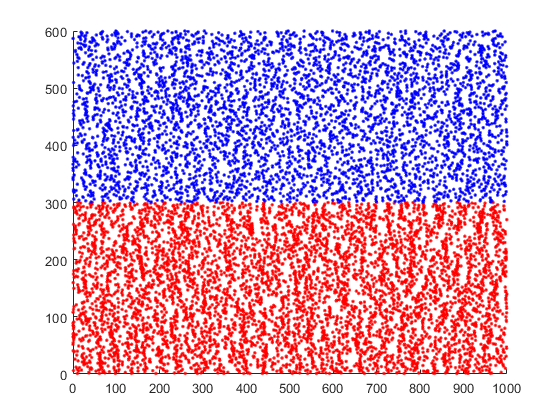

Nevent = floor(T*lambda*2);
eventsN = zeros(N,Nevent);
for ii = 1:N
    event = Poisson_Process_2(lambda,T);
    eventsN(ii,1:length(event))=event;
end

Vs  = cell(N_Sample,1);
spike = cell(N_Sample,1);
SpikeCount = cell(N_Sample,1);
t   = cell(N_Sample,1);
spiketime = cell(N_Sample,1);

WinSize  = 40;
WinSlide = 20;
%convcurve = [];
tic
for SamInd = 1:N_Sample
    V_0s = rand(N,1);
    [Vs{SamInd},spike{SamInd},t{SamInd},SpikeCount{SamInd},~,~] = ...
        MC_Vseries_for_network_ninput_I_based_norms_Syn(dt,T,V_0s,eventsN,fs,S, ...
                                                        see,sei,sie,sii,NE,NI,...
                                                        WinSize, WinSlide);
    [Sp_n,Sp_t] = find(spike{SamInd} == 1);
    spiketime{SamInd} = (Sp_t-1)*dt;
    
    if SamInd == 1
        figure
        [NeuInds,TInd] = find(spike{SamInd}>0);
        hold on
        scatter(TInd(NeuInds<=NE)*dt,NeuInds(NeuInds<=NE), 'r.')
        scatter(TInd(NeuInds>NE)*dt, NeuInds(NeuInds>NE),  'b.')
        hold off
        drawnow
        
        pause
    end
    SamInd
    %convcurve = [convcurve;abs(mean(rate_ns(:,1:6))-mean(rate_ns(:,7)))/N];
end

toc

## Trajs

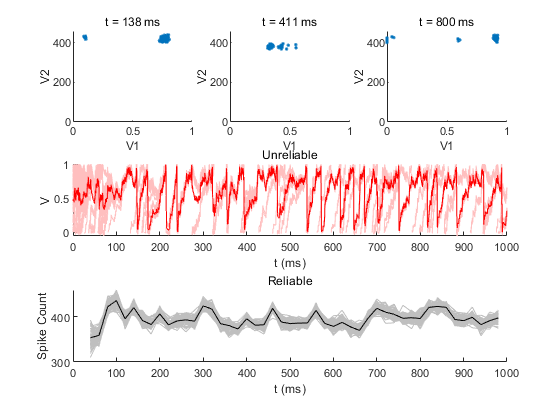

figure('Name','Figure 1')
NeuronInd1 = 2; % 16 20 100
subplot 312
hold on
VTrajAll = [];
for SamInd = 1:N_Sample   
    plot(t{SamInd},Vs{SamInd}(NeuronInd1,:),'Color',[1,0.75,0.75])
    VTrajAll = [VTrajAll;Vs{SamInd}(NeuronInd1,:)];
end
plot(t{SamInd}, mean(VTrajAll,'omitnan'),'r')
xlabel('t (ms)'); ylabel('V')
title('Unreliable')
%xlim([0 350])

subplot 313
hold on
WinNum = length(SpikeCount{SamInd}(NeuronInd1,:));
WinTimeFrame = (1:WinNum)*WinSlide+(WinSize - WinSlide);
FrTrajAll = [];
for SamInd = 1:N_Sample
    plot(WinTimeFrame,sum(SpikeCount{SamInd},1),'Color',[0.75,0.75,0.75])
    FrTrajAll = [FrTrajAll;sum(SpikeCount{SamInd},1)];
end
plot(WinTimeFrame,mean(FrTrajAll,1),'Color','k')
xlabel('t (ms)'); ylabel('Spike Count')
title('Reliable')
%xlim([0 350])


tShow = [59 486 956]; %ms
tim2DSample = cell(size(tShow));


% export V traj to all slected timepoints
for tShowInd = 1:length(tShow)
    tim2DSample{tShowInd} = zeros(N_Sample,2);
    tInd = floor(tShow(tShowInd)/dt);
    WinInd = floor(tShow(tShowInd)/WinSlide);
    for SamInd = 1:N_Sample
        tim2DSample{tShowInd}(SamInd,1) = (Vs{SamInd}(NeuronInd1,tInd));
        tim2DSample{tShowInd}(SamInd,2) = sum(SpikeCount{SamInd}(:,WinInd));
    end
    subplot(3,length(tShow),tShowInd)
    scatter(tim2DSample{tShowInd}(:,1),tim2DSample{tShowInd}(:,2),'.');
    xlabel('V');ylabel('Spike Count');
    title(sprintf('t = %d ms',tShow(tShowInd)))
    axis([0 1 0 max(FrTrajAll,[],'all')])
end

figure('Name','Raster')
SamIndShow  = [1,3,9 15, 18, 55];
for SamIndShowInd = 1:length(SamIndShow)
    subplot(3,2,SamIndShowInd)
    SamInd = 1;
    
    [NeuInds,TInd] = find(spike{SamIndShow(SamIndShowInd)}>0);
    hold on
    scatter(TInd(NeuInds<=NE)*dt,NeuInds(NeuInds<=NE), 'r.')
    scatter(TInd(NeuInds>NE)*dt, NeuInds(NeuInds>NE),  'b.')
    hold off
    xlim([0 300])
end
subplot 326
xlabel('t (ms)')